
groundTruth = readNPY('y_test.npy');
label = readNPY('X_test_lable.npy');

% Load the relevant data prediction results
groundTruth_Real = exp(double(readNPY('y_test_log_5Nor.npy')));
groundTruth_LSTM = exp(double(readNPY('y_test_pre_5_Nor_3L_detrend.npy')+trend_data(43)));
%groundTruth_Panel = predicted_yield;
label = readNPY('X_test_log_lable_5Nor.npy');
%PredictedData2020 y_train_log_5Nor_detrend
% groundTruth(isinf(groundTruth)) = nan;
aa1 = double(readNPY('y_test_pre_5_Nor_3L_detrend.npy'));

all_result = cat(2,PredictedData2020,PredictedData2020);
for i = 1:4432
    coun = PredictedData2020(i,1);
    flag = (label==coun);
    containsOne = any(flag);
    if containsOne==1
        all_result(i,3)=groundTruth_Real(flag);
        all_result(i,4)=groundTruth_LSTM(flag);
    else
        all_result(i,3)=nan;
        all_result(i,4)=nan;
    end
end
%得到的all_result 第一至4列分别代表：
%unid，panel model result, 实际情况, LSTM result
%保存为all_result_ouput
    




groundTruth = readNPY('y_test_pre_5_Nor_3L.npy');
aa = groundTruth(1:100,1,:);

load("all_result_ouput.mat");
min_exb = min(min(all_result(:,2:4)));
max_exb = 10000;



这里往下就调教好的代码

The following is to read the administrative scope shp data for Brazil and then match the results against the county id and visualize them

写一个输入CSV读取 这部分根据读入excel的不同 直接进行数据预处理

% %这里控制需要读入的CSV
% xlsFile = 'E:\SYSU\BRAZIL\Statistic of agricultural production in Brazil\Climate\Brazil_wether condition\C_Climate_PDSI_Hdd30\CBrazil_pointdata_allocate_1979_first_whether.csv';
% 
% data_xlsFile = readmatrix(xlsFile);
% 
% data_xls_process = data_xlsFile;
% data_xls_process(:,4) = data_xls_process(:,4).*4;
%data_xls_process(:,4) =  (data_xls_process(:,2) +data_xls_process(:,3))./20;
%%%data = cat(2,data_xls_process(:,1),data_xls_process(:,4)); %就改data就行
%data(:,2) = data(:,2)/100;
%data = cat(2,uni_county,mean(Matrix_PotentialYield_areaDecided,2));
%data = cat(2,label,groundTruth);
% data = PredictedData2020;

%data = cat(2,all_result(:,1),all_result(:,2));%Panel model 结果
%data = cat(2,all_result(:,1),all_result(:,3));%Ground Truth 结果
%data = cat(2,all_result(:,1),all_result(:,2)-all_result(:,3));%LSTM 结果
data = cat(2,label,groundTruth_LSTM);
data(data(:, 2) > 10000, 2) = 10000;

% data(data(:, 2) > 9000, 2) = 9000;
% data(data(:, 2) < -9000, 2) = -9000;


% 替换 'your_shapefile.shp' 和 'your_shapefile.dbf' 为您的Shapefile文件的实际文件名
shpfile = 'E:\SYSU\BRAZIL\BR_Municipios_2021\BRMunicipios_dissolve.shp';
dbffile = 'E:\SYSU\BRAZIL\BR_Municipios_2021\BRMunicipios_dissolve.dbf';
% 使用shaperead函数读取Shapefile数据
shpdata = shaperead(shpfile, 'UseGeoCoords', true);
% 使用dbfread函数读取DBF文件（属性表）
%dbfdata = dbfread(dbffile);
[num, txt, raw] = xlsread(dbffile);
% 从属性表中提取人口数量数据

% 假设data是你的数据矩阵，第一列是ID，第二列是属性值
unique_ids = unique(data(:, 1)); % 获取唯一的ID值
unique_ids_shp = unique(str2double(raw(2:end,1))); % unique_ids_shp是按照特定顺序排列的ID向量

% 初始化一个空矩阵来存储平均值
averages = NaN(length(unique_ids_shp), 2);

% 循环遍历每个unique_ids_shp中的ID
for i = 1:length(unique_ids_shp)
    id = unique_ids_shp(i);
    if ismember(id, unique_ids)
        rows_with_id = data(data(:, 1) == id, :); % 选择具有相同ID的行
        average_value = mean(rows_with_id(:, 2)); % 计算属性值的平均值
        averages(i, :) = [id, average_value]; % 存储ID和平均值
    end
end
% 现在，averages矩阵包含了按照unique_ids_shp顺序排列的每个ID的平均属性值，不存在的ID使用NaN填充
exhibit_data = averages(:,2);


% 创建一个新的地图图形窗口
figure;

% 自定义颜色映射，红-蓝
% customColors = [
%     187 64 62;     % 颜色1
%     224 116 103;   % 颜色2
%     224 170 143;   % 颜色3
%     254 212 198;   % 颜色4
%     203 223 234;   % 颜色5
%     159 198 215;   % 颜色6
%     101 156 187;   % 颜色7
%     66 124 172;    % 颜色8
% ]/255;

% 自定义颜色映射，蓝-红
% customColors = [
%     66 124 172;    % 颜色8
%     101 156 187;   % 颜色7
%     159 198 215;   % 颜色6
%     203 223 234;   % 颜色5
%     254 212 198;   % 颜色4
%     224 170 143;   % 颜色3
%     224 116 103;   % 颜色2
%     187 64 62;     % 颜色1
% ]/255;
%学习一下nature food的配色
customColors = [
    254 254 204;
    179 225 188;
    138 202 188;
    73 185 196;
    48 132 179;
    35 62 141;
    ]/255;


% 获取人口数量数据的最小值和最大值，用于划分颜色组
% min_exb = min(exhibit_data);
% max_exb = max(exhibit_data);
% min_exb = -9000;
% max_exb = 9000;
% 计算每个颜色组的区间
%colorRanges = linspace(min_exb, max_exb, 9);
colorRanges = linspace(min_exb, max_exb,7);

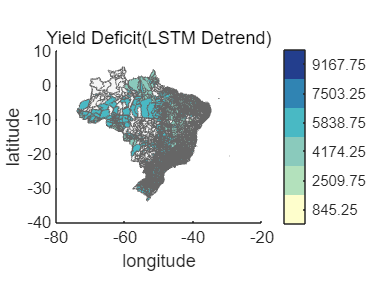


% 循环遍历每个行政区域，根据人口数量进行着色
for i = 1:numel(shpdata)
    % 获取经度（LON）和纬度（LAT）字段的值，形成多边形坐标
    geom = shpdata(i).Geometry;
    lon = shpdata(i).Lon;
    lat = shpdata(i).Lat;

    % 获取当前区域的人口数量
    exb = exhibit_data(i); 

    if isnan(exb)
        color=[245/255,245/255,245/255];
    else

        % 查找人口数量属于的颜色组
        color_group = find(exb >= colorRanges, 1, 'last');
        %因为四舍五入 然后就判断成9了 这里简单修改一下吧
        % if color_group == 9
        %     color_group = 8;
        if color_group ==7
            color_group = 6;
        end
        % 获取相应的颜色
        color = customColors(color_group, :);
    end


    % 绘制当前区域的多边形并填充颜色
    geoshow(lat, lon, 'DisplayType', 'polygon', 'FaceColor', color,'LineWidth', 0.5, 'EdgeColor', [0.4 0.4 0.4]);
    hold on;
end

% 添加颜色栏
colormap(customColors);
colorbar;

% 设置颜色栏的刻度和标签
colorbarTicks = colorRanges(1:end-1) + diff(colorRanges)/2;
colorbarLabel = arrayfun(@num2str, colorbarTicks, 'UniformOutput', false);
%colorbarTicks(end) = max_exb; % 确保最后一个刻度等于最大人口数量
c = colorbar;
%c.Ticks = colorbarTicks;
%c.Ticks = [0.125, 0.25, 0.375,0.5,0.625,0.75,0.875,1];
%c.Ticks = [0.167, 0.333, 0.5, 0.667, 0.833, 1];
c.Ticks = [0.083, 0.25, 0.417, 0.583, 0.75, 0.917];
DoubleLabel = str2double(colorbarLabel);
DoubleLabel = round(DoubleLabel, 3);

CellLabel = num2cell(DoubleLabel);

c.TickLabels = CellLabel;
%c.FontSize = 10; % 根据需要调整字体大小 默认是10-12

% 设置标题和标签
title('Yield Deficit(LSTM Detrend)');
%title('BRAZIL CORN YIELD IN 2022 (Ground Truth)');
%title('Yield Deficit(LSTM - Ground Truth)');
xlabel('longitude');
ylabel('latitude');

% 使用 export_fig 保存图形
%outputFileName = 'high_res_map_PDSI1_mycolor.jpg';  % 保存文件的名称和格式（可以根据需要更改为其他格式）
%export_fig(outputFileName, '-r300', '-transparent');  % 保存为高分辨率图像，-r 指定分辨率


%现在的任务 就是在最前面加一个 多读几组数据 取最大最小值 这样就能统一坐标轴

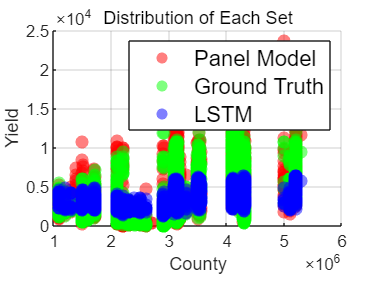

% Visualize the distribution of prediction results and ground truth
% 提取横坐标和纵坐标的数据
x_data = all_result(:, 1);
y_data1 = all_result(:, 2);
y_data2 = all_result(:, 3);
y_data3 = all_result(:, 4);

% 绘制散点图
figure;
scatter(x_data, y_data1, 50, 'r', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(x_data, y_data2, 50, 'g', 'filled', 'MarkerFaceAlpha', 0.5);
scatter(x_data, y_data3, 50, 'b', 'filled', 'MarkerFaceAlpha', 0.5);


% 添加图例
legend('Panel Model', 'Ground Truth', 'LSTM');
% 设置图例字体大小
set(legend, 'FontSize', 12);  % 你可以根据需要调整字体大小

% 添加轴标签和标题
xlabel('County');
ylabel('Yield');
title('Distribution of Each Set');

% 显示网格线
grid on;

% 显示绘图
hold off;

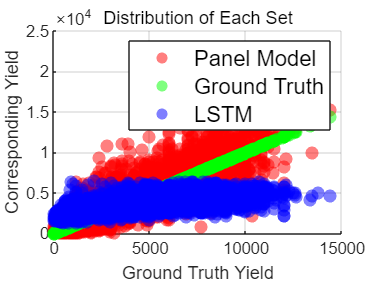

% 提取横坐标和纵坐标的数据
x_data = all_result(:, 3);
y_data1 = all_result(:,2);
y_data2 = all_result(:,3);
y_data3 = all_result(:,4);

% 绘制散点图
figure;
scatter(x_data, y_data1, 50, 'r', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(x_data, y_data2, 50, 'g', 'filled', 'MarkerFaceAlpha', 0.5);
scatter(x_data, y_data3, 50, 'b', 'filled', 'MarkerFaceAlpha', 0.5);

% 添加图例
legend('Panel Model', 'Ground Truth', 'LSTM');
% 设置图例字体大小
set(legend, 'FontSize', 12);  % 你可以根据需要调整字体大小

% 添加轴标签和标题
xlabel('Ground Truth Yield');
ylabel('Corresponding Yield');
title('Distribution of Each Set');

% 显示网格线
grid on;

% 显示绘图
hold off;

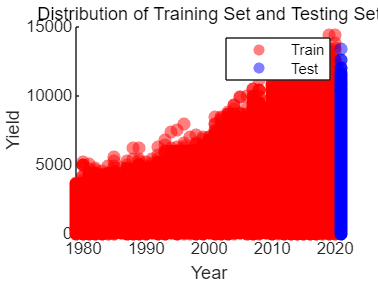

% View the difference in distribution between the training set and the test set
%看一看训练set和测试set的yield的分布
train = exp(CORN_data2020(:,12));
test = exp(CORN_data_new(:,12));
% 绘制散点图
figure;
scatter(CORN_data2020(:,2), train, 50, 'r', 'filled', 'DisplayName', 'Train', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(CORN_data_new(:,2), test, 50, 'b', 'filled', 'DisplayName', 'Test', 'MarkerFaceAlpha', 0.5);

% 添加图例
legend('show');

% 添加轴标签和标题
xlabel('Year');
ylabel('Yield');
title('Distribution of Training Set and Testing Set');

% 显示绘图
hold off;

%
LSTM = readNPY('y_test_pre_5_Nor_3L.npy');
pr = readNPY('Predict_disturbe_Pr.npy');
temp = readNPY('Predict_disturbe_Temp.npy');

irri = readNPY('Predict_disturbe_Irri.npy');
fert = readNPY('Predict_disturbe_Fert.npy');

om = readNPY('Predict_disturbe_OM.npy');
sand = readNPY('Predict_disturbe_Sand.npy');
silt = readNPY('Predict_disturbe_Silt.npy');
clay = readNPY('Predict_disturbe_Clay.npy');

total = exp(cat(2,LSTM,pr,temp,irri,fert,om,sand,silt,clay));

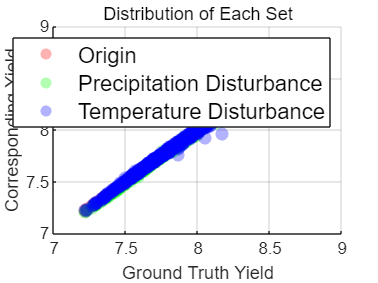

% 提取横坐标和纵坐标的数据
x_data = LSTM;
y_data1 = LSTM;
y_data2 = pr;
y_data3 = temp;

% 绘制散点图
figure;
scatter(x_data, y_data1, 50, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter(x_data, y_data2, 50, 'g', 'filled', 'MarkerFaceAlpha', 0.3);
scatter(x_data, y_data3, 50, 'b', 'filled', 'MarkerFaceAlpha', 0.3);

% 添加图例
legend('Origin', 'Precipitation Disturbance', 'Temperature Disturbance');
% 设置图例字体大小
set(legend, 'FontSize', 12);  % 你可以根据需要调整字体大小

% 添加轴标签和标题
xlabel('Ground Truth Yield');
ylabel('Corresponding Yield');
title('Distribution of Each Set');

% 显示网格线
grid on;

% 显示绘图
hold off;

% 假设 total 是你的数据矩阵
numCols = size(total, 2);

% 用于存储KL散度
klDivergences = zeros(1, numCols-1);

% 估计第一组数据的PDF
[pdf1, xi] = ksdensity(total(:,1));

% 计算其他组数据与第一组的KL散度
for col = 2:numCols
    [pdfN, ~] = ksdensity(total(:,col), xi);
    pdfN = pdfN + 1e-6; % 平滑处理
    klDiv = sum(pdfN .* log(pdfN ./ (pdf1 + 1e-6)));
    klDivergences(col-1) = klDiv;
end

% 输出结果
disp(klDivergences);

   1.0e-05 *

    0.2154    0.1918    0.3692    0.0085    0.2154    0.1318    0.1025    0.0987



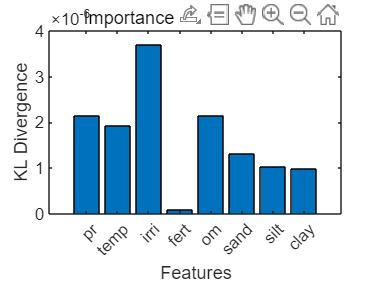

% 特征名称
features = {'pr', 'temp', 'irri', 'fert', 'om', 'sand', 'silt', 'clay'};

% 绘制条形图
figure;
bar(klDivergences);
set(gca, 'xticklabel', features);
xlabel('Features');
ylabel('KL Divergence');
title('Importance of Each Feature');